# 離散化とマイコン実装について

## 背景

制御器はコントローラに実装されることで、現実世界のプラントモデルを制御できるようになる。アルゴリズムは、近年はマイクロコントローラなどのソフトウェアで実装するのが基本である。しかし、マイクロコントローラの動作は離散的であり、古典制御理論が想定している連続動作とは異なっている。

本節では、アルゴリズムの離散化が必要な理由とその方法、設計実装時の注意点などを説明する。

## マイコンの動作について

マイクロコントローラに実装する処理はC言語の関数で記述する。関数は、割り込みイベントが発生したタイミングで呼び出され、実行される。割り込みイベントは自由に設計することができるが、制御のアルゴリズムを実行する場合は「タイマー割り込み」を用いる。

タイマー割り込みは、一定時間ごとに繰り返し処理を呼び出すイベントである。例えば、時間間隔$\textrm{ts}$ごとに呼び出される場合、Fig.1のように計算して待機、を繰り返す。（緑の部分は計算実行中を示す）

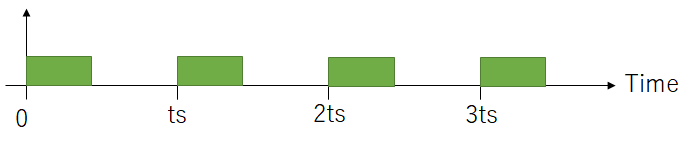

Fig.1 タイマー割り込みの処理

理想的には、コントローラには連続動作をさせたいが、アルゴリズムの計算やセンサー計測など、必ず一定の処理時間が必要となる。

もし$\textrm{ts}$を無限小にすることができれば、離散動作を限りなく連続動作に近づけることができるが、現実的には不可能であるため、設定可能な$\textrm{ts}$の最小値が存在している。

## 離散化

連続時間で設計した制御アルゴリズムは、実装のために離散化する。PID制御においては、比例器は変換する必要はなく、積分器、微分器は変換が必要である。

z変換の理論では、離散化の手法として次数の高い（計算コストのかかる）アルゴリズムで、より正確に積分値、微分値を求める様々な手法が提案されている。しかし、PID制御の離散化で高度な手法を用いる必要はない。積分値、微分値が真値と異なっていたことによるPID制御器の性能の変化は、現実のプラントモデルをモデル化した際のモデル化誤差で引き起こされる性能の変化と比較した場合、ほとんどの場合でモデル化誤差の影響の方が大きい。従って、離散化誤差はモデル化誤差に埋もれて、全く目立たなくなるのである。

そこで、離散化は最も簡単な手法を用いることにする。最も簡単な離散化手法としては「後退オイラー法」がある。積分器は(eq.1)のように離散化することができる。


$$y\left\lbrack k\right\rbrack =y\left\lbrack k-1\right\rbrack +K_i \cdot \textrm{ts}\cdot u\left\lbrack k\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{eq}\ldotp 1\right)$$


ここで、$K_i$はIゲイン、$y\left\lbrack k\right\rbrack$は積分器の出力、$u\left\lbrack k\right\rbrack$は積分器の入力、$k$は今のステップの値、$k-1$は前回のステップの値を意味する。

一方微分器は、(eq.2)のようになる。


$$y\left\lbrack k\right\rbrack =K_d \cdot \frac{\left(u\left\lbrack k\right\rbrack -u\left\lbrack k-1\right\rbrack \right)}{\textrm{ts}}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{eq}\ldotp 2\right)$$


ここで、$K_d$はDゲイン、$y\left\lbrack k\right\rbrack$は微分器の出力、$u\left\lbrack k\right\rbrack$は微分器の入力、$k$は今のステップの値、$k-1$は前回のステップの値を意味する。

(eq.1)、(eq.2)の処理は、C言語などのプログラミング言語で表現することができる。$\left\lbrack k\right\rbrack$の値を保持し、次回の計算ステップでその値を$\left\lbrack k-1\right\rbrack$の値として用いればよい。

## Simulinkモデル

上記(eq.1)、(eq.2)はSimulinkブロックなどを用いて実装することができるが、「PID Controller」ブロックを用いれば、ブロックパラメータの設定を切り替えるだけで離散化できる。

ブロックパラメータの「時間領域」で「離散時間」を選択し、サンプル時間を指定する（接続元ブロックからサンプル時間を継承できる場合は-1でよい）。「離散時間指定」の「積分器とフィルターの手法」で「後退オイラー法」を選択する。

入力を指令値とセンサー値、出力を制御の操作量として、一つのモデルを作成した。「DSD_PID_controller.slx」を開いてモデルを確認する。

controller_model_name = 'DSD_PID_controller';
open_system(controller_model_name);

指令値とセンサー値の差分の計算と、PID制御の計算をまとめて「制御を計算する関数」としたい。そのため、その二つをまとめて一つのモデルにしている。「DSD_PID_controller.slx」のコンフィギュレーションパラメータで、Embedded Coder®によるCコード生成が設定されている。Embedded Coder®のライセンスがある場合、Simulinkキャンバス上で"Ctrl + B"を入力することでコード生成することができる。

コード生成の手法については制御設計の範疇ではないため、本節では説明しない。コード生成の結果のみ、参考までに紹介する。

コード生成をすると、「（モデル名）_step」「（モデル名）_initialize」「（モデル名）_terminate」の三つの関数が生成される。initialize関数は最初に一度だけ、terminate関数は最後に一度だけ実行する。ただし、今回の制御モデルにおいてはinitialize、terminate関数で実行すべき処理はないので、この二つは用いなくてよい。step関数は、tsの時間間隔で呼び出されるタイマー割り込みで呼び出す。

以下に、生成されたコードを示す。

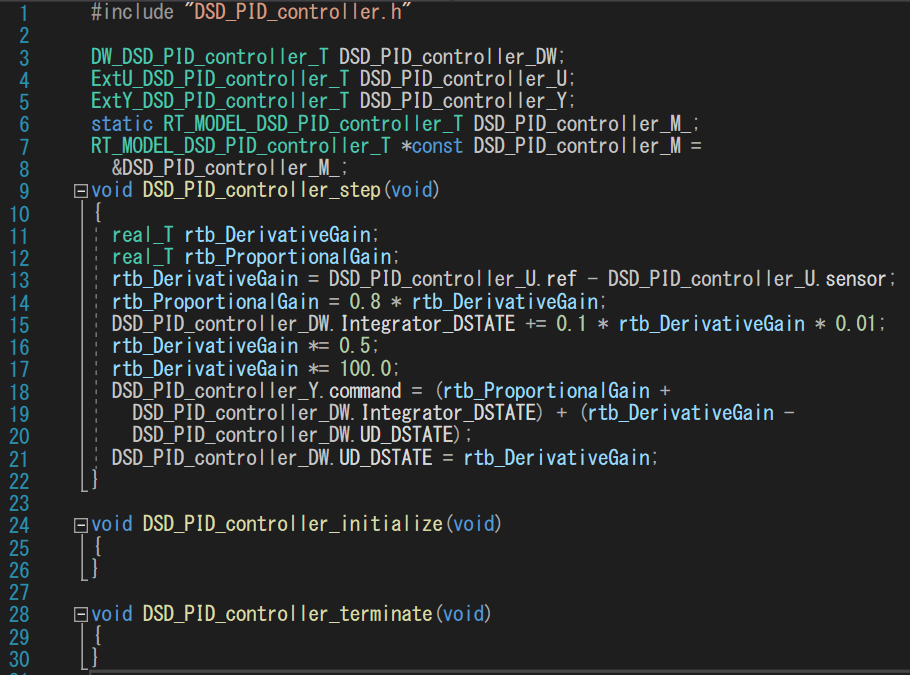

構造体DSD_PID_controller_DW、DSD_PID_controller_U、DSD_PID_controller_Yはスタティックな変数であるため、次回の関数呼び出し時にも値が保持されている。

### Task 1

上記コードを読み、後退オイラー法の積分、微分が実装されていることを確認すること。

制御モデルは、「参照モデル」機能で上位のモデルから呼び出すことができ、プラントモデルと接続して動作をシミュレーションで確認することができる。モデル「DSD_control_system.slx」を開いて確認すること。

open_system('DSD_control_system');

[（Part 3: ゲインチューニング）戻る](matlab:(proceed_live_page('UHG_control_UAV_p3.mlx')))　|　[進む（PID設計のガイド）](matlab:(proceed_live_page('PDG_design_guide.mlx')))

*Copyright 2021 The MathWorks, Inc.*